# **demo11 of Im2mesh package**

demo11 - Use Gmsh as mesh generator

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com. [Project website](https://github.com/mjx888/im2mesh).

## Note

I suggest familiarizing yourself with [Im2mesh_GUI](https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh) before learning Im2mesh package. With graphical user interface, Im2mesh_GUI will help you better understand the workflow and parameters of Im2mesh package. No need to install any MATLAB toolboxes when running this demo.

Gmsh can be downloaded from [https://gmsh.info/bin/](https://gmsh.info/bin/) or [https://gmsh.info](https://gmsh.info)

If you plan to generate quadrilateral mesh, please download gmsh-4.13 or gmsh-4.14. I encountered a bug when using gmsh-4.15 to generate quadrilateral mesh.

## Initialize

**Before starting, we need to download Gmsh and un-zip.**

clearvars

We need to know the location of gmesh.exe

% for example
path_to_gmsh = 'C:\Users\Jason\Downloads\gmsh-4.13.1-Windows64\gmsh.exe';

Please set folder "Im2mesh_Matlab" as your current folder of MATLAB.

Set default image size (optional).

x = 250; y = 250; width = 250; height = 250;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

We add the folder 'mesh2d-master' to the path of MATLAB. 

addpath(genpath('mesh2d-master'))

## Get boundries from image

We have demostrate how to do this in example3 of demo01.mlx

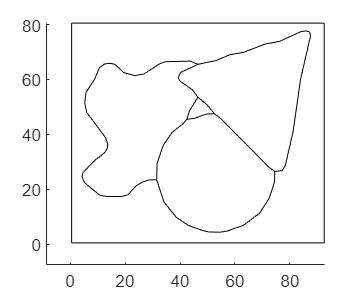

im = imread('Shape.tif');
if size(im,3) == 3;  im = rgb2gray( im ); end

opt = [];   % reset opt
opt.tolerance = 0.3;
opt.tf_mesh = false;

bounds = im2mesh( im, opt );

% bounds is the simplified polygonal boundaries
plotBounds( bounds );

### Phase selection before meshing

Suppose we don't need the background.

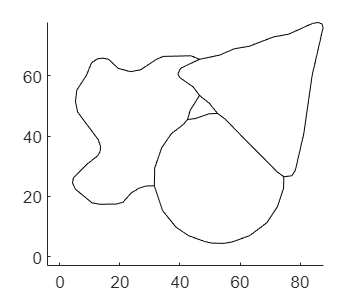

select_phase = [2 3 4];
bounds = bounds( select_phase );
plotBounds( bounds );

## Unstructured triangular mesh

### Write geo file for Gmsh

geo file is a text file that contains Gmsh’s own scripting language. It’s used to define geometry and mesh generation instructions for Gmsh.

We use function bounds2geo to generate geo file. 

% setup parameters
opt = [];   % reset
opt.sizeMin = 0.1;
opt.sizeMax = 6;
opt.algthm = 6;
opt.recombAll = 0;
opt.recombAlgthm = 3;
opt.eleOrder = 1;
opt.num_split = 0;
opt.grad_mode = 0;

path_to_geo = 'gmshTemp.geo';

bounds2geo( bounds, path_to_geo, opt );

bounds2geo Done! Check the geo file!


We will see a geo file 'gmshTemp.geo' generated in the current working folder of MATLAB.

There are many parameters for function bounds2geo. You can open bounds2geo.m to take a look at their meanings

Here is the general guideline for choosing the value of these parameters:

 1. To generate triangular mesh, you can set opt.algthm to 1-7 and set opt.recombAll to 0.

 2. To generate unstructured quadrilateral mesh, you can set opt.algthm to 8 and set opt.recombAll to 1. You can try different opt.recombAlgthm.

 3. To generate quasi-structured quadrilateral mesh, you can set opt.algthm to 11 and set opt.recombAll to 0.

 4. When opt.grad_mode is 0, you can adjust the value of opt.sizeMax to achieve better mesh quality. Typical value of opt.sizeMax is 4 to 20.

 5. When opt.grad_mode is 1, you can adjust opt.sizeAtBound, opt.sizeSlope, and opt.sizeMax to achieve better mesh quality.

 6. When opt.grad_mode is 2, you can set opt.sizeAtBound to a larger value (e.g., 10-500) and adjust opt.sizeSlope.

### Generate mesh via Gmsh

After we got the geo file, we use the following command to send the geo file to Gmsh. Gmsh will generate a m file 'gmshTemp.m'. 

path_to_m = 'gmshTemp.m';
verbosity = 3;

str=sprintf('"%s" "%s" -o "%s" -v %i -save', ... 
			path_to_gmsh, path_to_geo, path_to_m, verbosity );
system(str);

When we run the m file, we will see a struct variable 'msh' in the workspace of MATLAB.

% run m file
run(path_to_m)
msh

msh = struct with fields:
        nbNod: 435
          POS: [435×3 double]
          MAX: [87.5400 77.7000 0]
          MIN: [4.3100 4.3800 0]
    TRIANGLES: [786×4 double]


Then, we can use function extractMsh to extract nodes and elements from the struct variable 'msh'. Function extractMsh also works for quadratic elements.

[vert,ele,tnum] = extractMsh( msh );

 254 negative area elements are fixed.


### Plot mesh

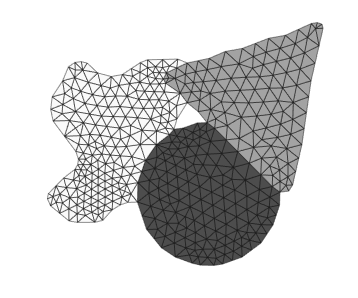

plotMeshes(vert,ele,tnum)

We can use function tricost to check the mesh quality. Function tricost is written by by Darren Engwirda.

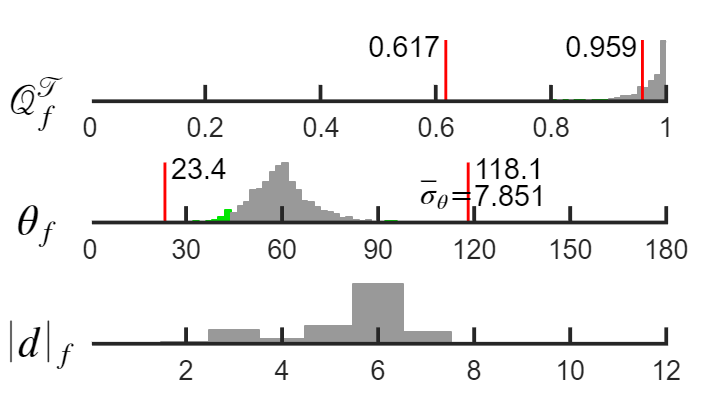

tricost( vert, ele );

## Export mesh via Gmsh

After we got the mesh, we can use Gmsh or the functions in demo03 to export it. 

Suppose we want to use Gmsh to export mesh as inp file 'gmshExport.inp'.

path_to_file = 'gmshExport.inp';
verbosity = 3;

str=sprintf('"%s" "%s" -o "%s" -v %i -save', ... 
			path_to_gmsh, path_to_geo, path_to_file, verbosity );
system(str);

We should be able to see a file 'gmshExport.inp' in current working folder of Matlab.

## Unstructured quadrilateral mesh

### Write geo file and generate mesh via Gmsh

We can use Gmsh to generate unstructured quadrilateral mesh by setting opt.algthm to 8 and set opt.recombAll to 1.

% setup parameters
opt = [];   % reset
opt.sizeMin = 0.1;
opt.sizeMax = 6;
opt.algthm = 8;
opt.recombAll = 1;
opt.recombAlgthm = 3;
opt.eleOrder = 1;
opt.num_split = 0;
opt.grad_mode = 0;

path_to_geo = 'gmshTemp.geo';

bounds2geo( bounds, path_to_geo, opt );

bounds2geo Done! Check the geo file!



path_to_m = 'gmshTemp.m';
verbosity = 3;
str=sprintf('"%s" "%s" -o "%s" -v %i -save', ... 
			path_to_gmsh, path_to_geo, path_to_m, verbosity );
system(str);

Gmsh will generate a m file. When we run the m file, we will see a struct variable 'msh' in the workspace of MATLAB.

% run m file
run(path_to_m)
msh

msh = struct with fields:
    nbNod: 894
      POS: [894×3 double]
      MAX: [87.5400 77.7000 0]
      MIN: [4.3100 4.3800 0]
    QUADS: [828×5 double]


Then, we can use function extractMsh to extract nodes and elements from the struct variable 'msh'. Function extractMsh also works for quadratic elements.

[vert,ele,tnum] = extractMsh( msh );

 203 negative area elements are fixed.


### Plot mesh

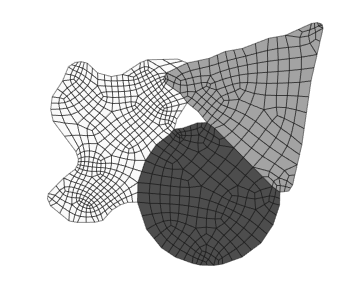

plotMeshes(vert,ele,tnum)

Awesome!

### Mesh quality

We can use function [MeshQualityQuads](https://www.mathworks.com/matlabcentral/fileexchange/33108-unstructured-quadrilateral-mesh-quality-assessment) (written by Allan Peter Engsig-Karup) to evaluate mesh quality.

[Q,theta] = MeshQualityQuads( ele(:,1:4), vert(:,1), vert(:,2) );

Mean value of Q

mean_Q = mean(Q)

mean_Q = 0.6557

Standard deviation of theta (in degree)

std_theta = std( rad2deg(theta(:)) )

std_theta = 14.1113

Plot histogram of Q

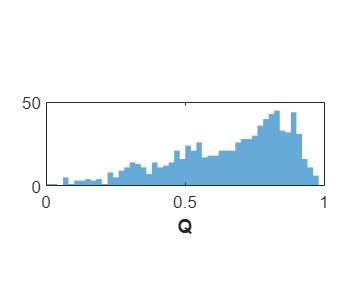

histogram( Q, 'BinWidth', 0.02, 'BinLimits', [0,1], ...
			'EdgeColor', 'none');
xlabel('Q','FontSize',10,'FontWeight','bold');
pbaspect([2 0.6 1]);

After we got the mesh, we can use Gmsh or the functions in demo03 to export it.

% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo